#  KUKA-KR10-R1100-2 Robotic arm

Github Link : [https://github.com/mostafa-metwaly/DoNRs-HW3](https://github.com/mostafa-metwaly/DoNRs-HW3)

Mostafa Osama 

Innopolis University

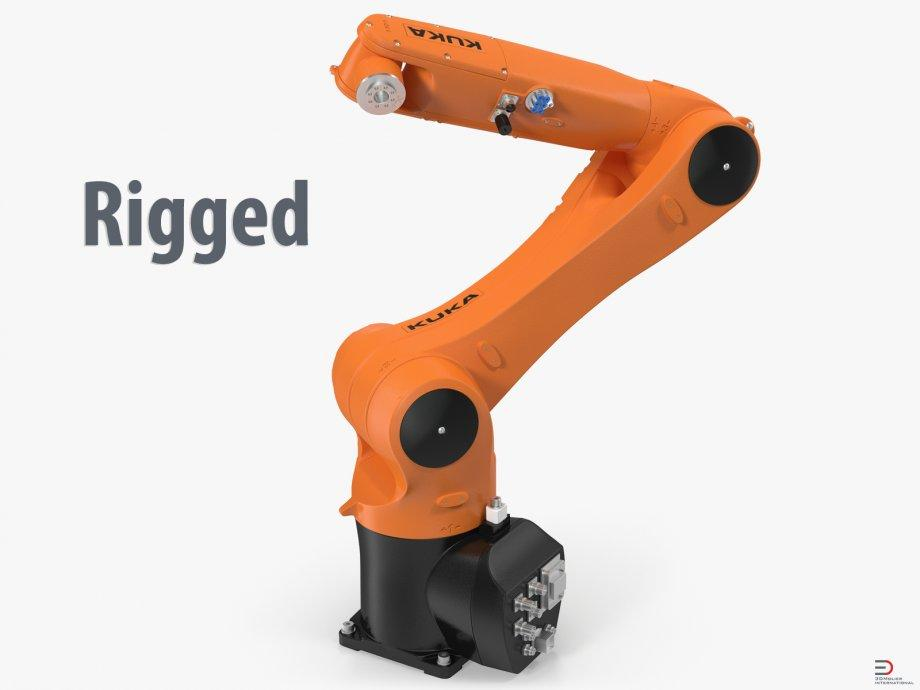

clear all
close all
clc
% set angles as symbolical
syms q1 q2 q3 q4 q5 q6 real
%Link lengths
d1=0.4;d2=0.025;d3=0.56;d4=0.025;d5=0.515;d6=0.09;
d=[d1, d2, d3, d4, d5, d6];

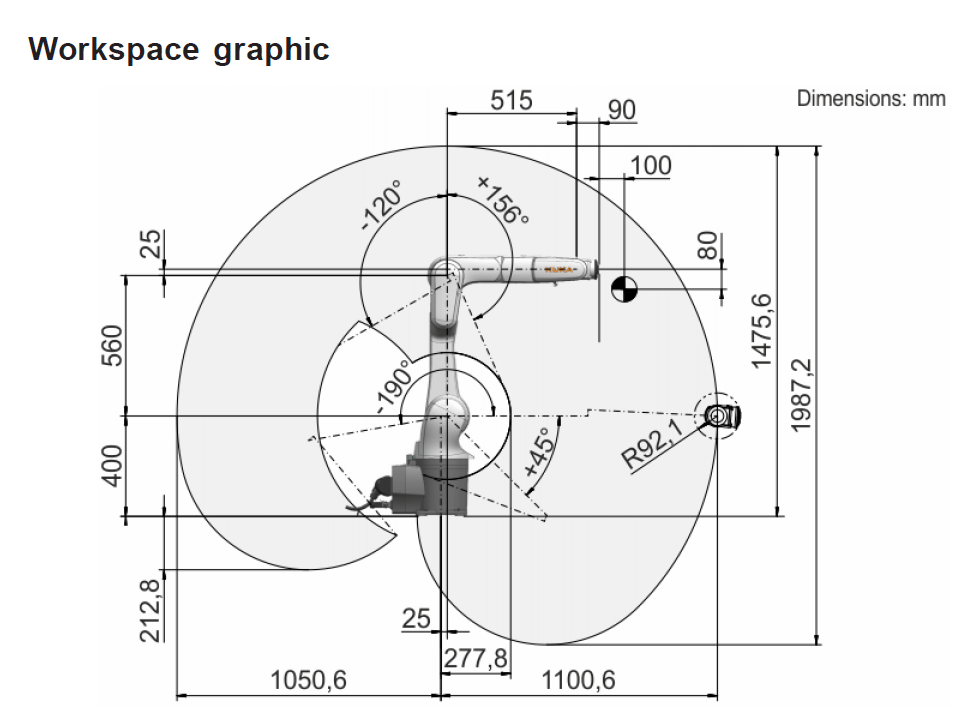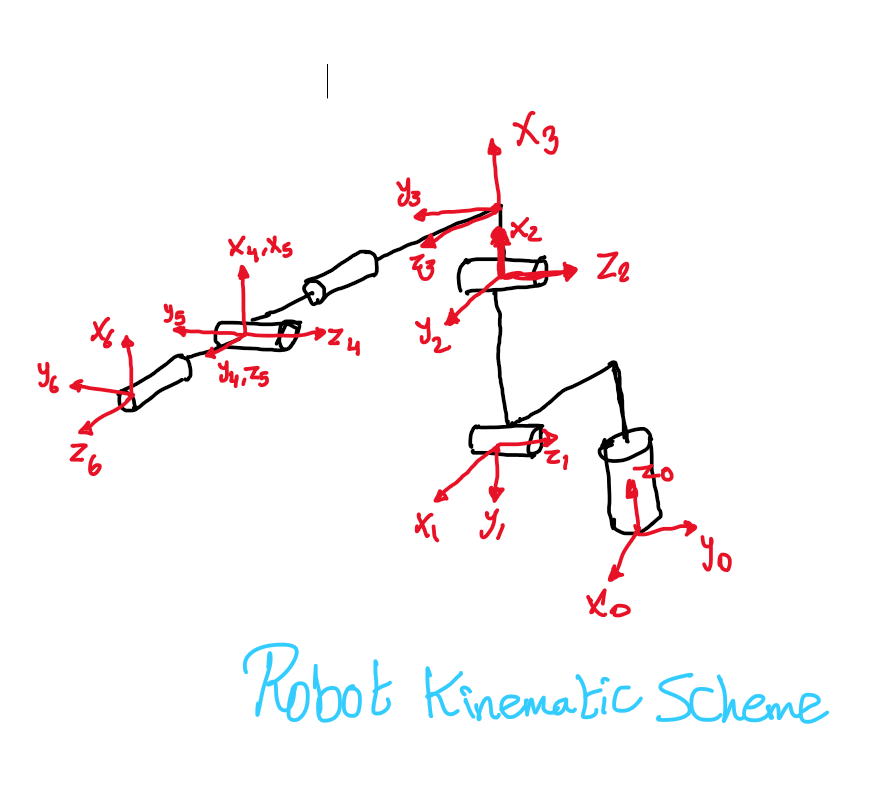

## Forward Kinematics


$$H=R_z \left(\textrm{q1}\right)\cdot T_z \left(\textrm{d1}\right)\cdot R_x \left(-\textrm{q2}\right)\cdot T_x \left(\textrm{d2}\right)\cdot R_z \left(\textrm{q3}\right)\cdot T_x \left(\textrm{d3}\right)\;\;\cdot R_z \left(\textrm{q4}\right)\cdot T_z \left(\textrm{d4}\right)\cdot R_x \left(\textrm{q5}\right)\cdot T_x \left(\textrm{d5}\right){\cdot R}_z \left(\textrm{q6}\right)\cdot T_z \left(\textrm{d6}\right)$$


% FK symbolical
FK=simplify(Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6))


disp('All 0 configuration')

All 0 configuration


q_test = [0 0 0 0 0 0] % all 0 configuration

q_test =      0     0     0     0     0     0


draw_robot(q_test,d)

q6 = 0

d6 = 0.0900

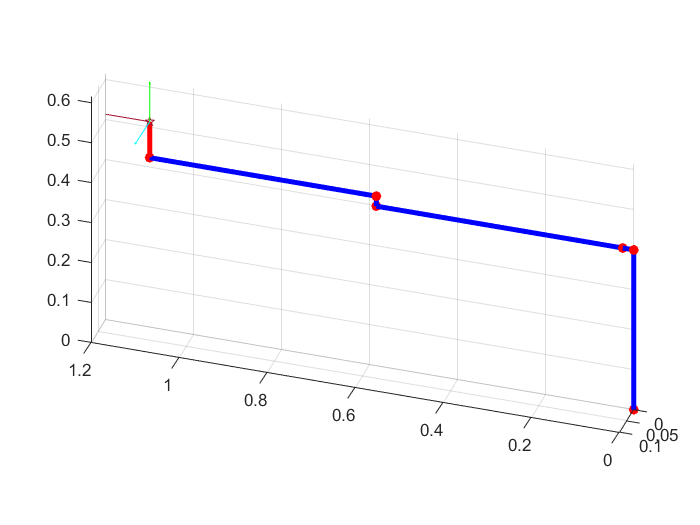


view([198.474 30.562])

% Substitute angles in symbolical form and convert to double
double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

ans =     1.0000         0         0    1.1000
         0    1.0000         0         0
         0         0    1.0000    0.5150
         0         0         0    1.0000



disp('Random configuration')

Random configuration



q1v=-20*pi/180;
q2v=40*pi/180;
q3v=-60*pi/180;
q4v=30*pi/180;
q5v=30*pi/180;
q6v=30*pi/180;
q_test=[q1v q2v q3v q4v q5v q6v]

q_test =    -0.3491    0.6981   -1.0472    0.5236    0.5236    0.5236


q6 = 0.5236

d6 = 0.0900

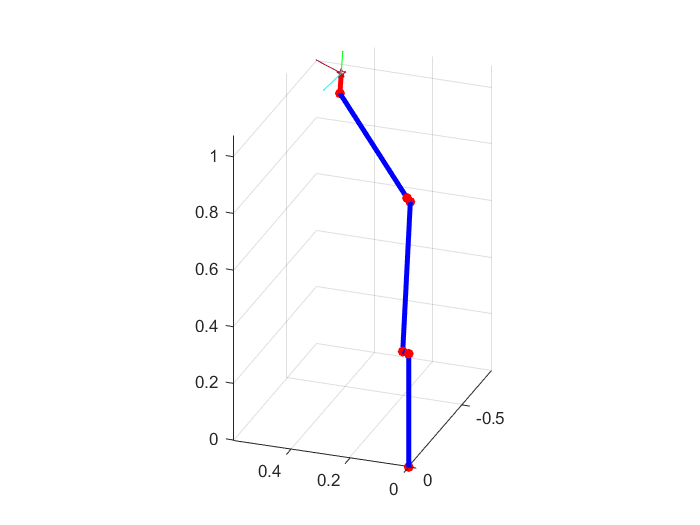

draw_robot(q_test,d)

% Substitute angles in symbolical form and convert to double
double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

ans =     0.9480    0.2764   -0.1580    0.5025
   -0.2213    0.9289    0.2969   -0.7495
    0.2288   -0.2465    0.9417    0.9812
         0         0         0    1.0000



% disp('Test configuration')
% q_test = [pi/3 -pi/6 11 -1 -1 -1] % test configuration
% draw_robot(q_test,L)
% Substitute angles in symbolical form and convert to double
T=double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

T =     0.9480    0.2764   -0.1580    0.5025
   -0.2213    0.9289    0.2969   -0.7495
    0.2288   -0.2465    0.9417    0.9812
         0         0         0    1.0000


## Jacobian

### Numerical derivatives

Forward kinematics

syms q1 q2 q3 q4 q5 q6 real
L1=10

L1 = 10

L2=20

L2 = 20

L3=30

L3 = 30

L=[L1, L2 L3];
H=simplify(Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6))

where

## 
$$H=\left\lbrack \begin{array}{cc}
R & T\\
0 & 1
\end{array}\right\rbrack$$


R = simplify(H(1:3,1:3))

% forward kinematics
H =Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6);
H=simplify(H);
% extract rotation matrix
R = simplify(H(1:3,1:3));
% diff by q1
Td=Rzd(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 1st column
J1 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q2
Td=Rz(q1)*Tz(d1)*Rxd(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J2 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q3
Td=Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rzd(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 3rd column
J3 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q4
Td=Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rzd(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rz(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 4th column
J4 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
Td=Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rxd(q5)*Tx(d5)*Rz(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 5th column
J5 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
Td=Rz(q1)*Tz(d1)*Rx(-q2)*Tx(d2)*Rz(q3)*Tx(d3) *Rz(q4)*Tz(d4)*Rx(q5)*Tx(d5)*Rzd(q6)*Tz(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 6th column
J6 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% Full Jacobian 6x6
Jq1 = [simplify(J1), simplify(J2), simplify(J3), simplify(J4), simplify(J5), simplify(J6)]

singularity=simplify(det(Jq1))